# EXP.8B PI Controller Implementation

z_PI = 5.6683;
K = 0.0530;

Gc = zpk(-z_PI, 0, 1) % define the compensator TF

Gc =
 
  (s+5.668)
  ---------
      s
 
Continuous-time zero/pole/gain model.
Model Properties


Tsamp = 0.01; %s
Gc_z = c2d(Gc,Tsamp,'tustin')

Gc_z =
 
  1.0283 (z-0.9449)
  -----------------
        (z-1)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


r = 45; % rad/s
a = 3.6345;
b = 68.5131;

% run the simulation
out = sim('PI_Controller_Z', 2);

F_v = mean(out.Y.Data(end-10:end)) % calculate final value

F_v = 44.9765


% t = out.Y.Time(out.Y.Data >= 0.98*F_v); % calculate times above -2% final value
t = out.Y.Time(out.Y.Data >= 1.02*F_v); % calculate times above -2% final value

T_s = t(end)

T_s = 1.0700


u0 = out.u.Data(1) % initial input voltage

u0 = 2.4525


SSE = 45 - F_v % calculate steady state error

SSE = 0.0235


OS = (findpeaks(out.Y.Data) - F_v) / F_v

OS = 0.0337


peak_input = findpeaks(out.u.Data)

peak_input = 2.8683

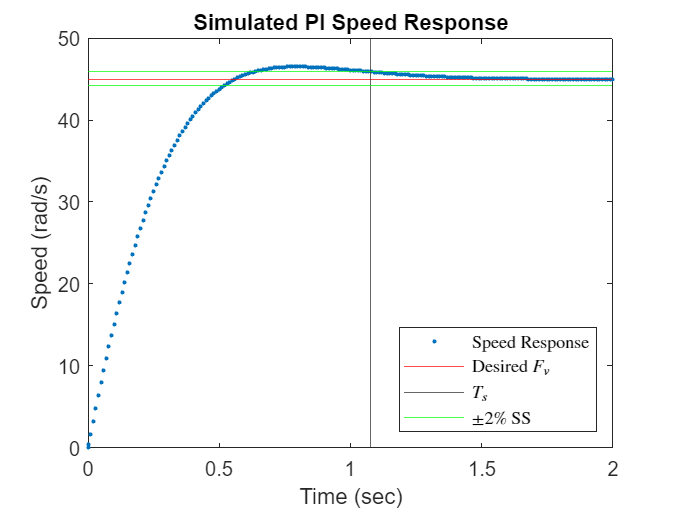

% plot speed response
plot(out.Y.Time, out.Y.Data, '.')
yline(45, 'r')
xline(T_s)
yline(F_v * 0.98, 'g')
%ylim([0 50])
yline(F_v * 1.02, 'g')
title("Simulated PI Speed Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend({"Speed Response", "Desired $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

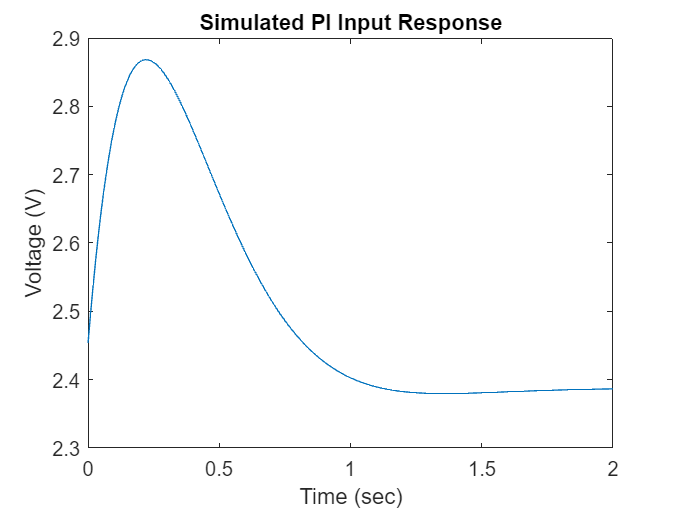


% plot input response
plot(out.u.Time, out.u.Data)
title("Simulated PI Input Response")
xlabel("Time (sec)")
ylabel("Voltage (V)")

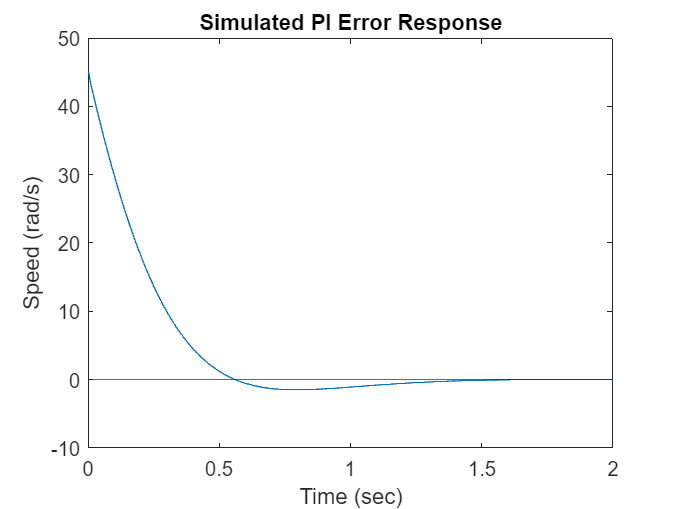


% plot error response
plot(out.e.Time, out.e.Data)
yline(0)
title("Simulated PI Error Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")

Open serial port.

clear s % closes ports already open
s = serialport('COM11',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM11"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Read serial port values and parse data into lists. 

t = zeros(1, 200);
pos = zeros(1, 200);
spd = zeros(1, 200);
inpt = zeros(1, 200);
error = zeros(1, 200);

% loop through all 
for n = 1:200
    msg = s.readline();
    items = split(msg, ',');
    vals = arrayfun(@str2num, items);
    t(n) = vals(1);
    pos(n) = vals(2);
    spd(n) = vals(3);
    inpt(n) = vals(4);
    error(n) = vals(5);
end

% save lab8b3_11192024.mat t pos spd inpt error

% load data from all three trials
trial1 = load('lab8b1_11192024.mat');
[B,I] = sort(trial1.t); % sort in correct order
time1 = B;
speed1 = trial1.spd(I);
input1 = trial1.inpt(I);
error1 = trial1.error(I);

trial2 = load('lab8b2_11192024.mat');
[B,I] = sort(trial2.t); % sort in correct order
time2 = B;
speed2 = trial2.spd(I);
input2 = trial2.inpt(I);
error2 = trial2.error(I);

trial3 = load('lab8b3_11192024.mat');
[B,I] = sort(trial3.t); % sort in correct order
time3 = B;
speed3 = trial3.spd(I);
input3 = trial3.inpt(I);
error3 = trial3.error(I);

% calculate mean values
time = (time1 + time2 + time3) / 3;
speed = (speed1 + speed2 + speed3) / 3;
input = (input1 + input2 + input3) / 3;
error = (error1 + error2 + error3) / 3;

% calculate F_v, T_s, and %OS
F_v = mean(speed(150:end)) % steady state speed

F_v = 45.0659

i = find(speed >= 1.02 * F_v);
T_s = time(i(end-2))

T_s = 1.0743

OS = (max(speed)-F_v)/F_v

OS = 0.0484

Plot speed, angle and input voltage with respect to time. 

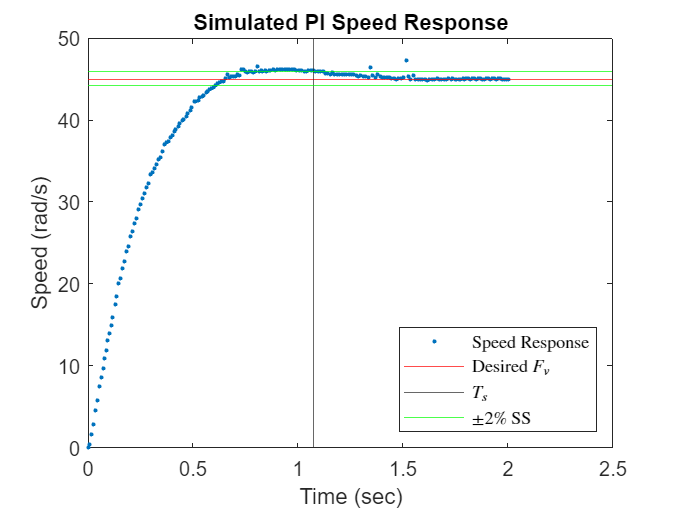

% plot speed
plot(time,speed, '.')
yline(45, 'r')
xline(T_s)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
title("Simulated PI Speed Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend({"Speed Response", "Desired $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

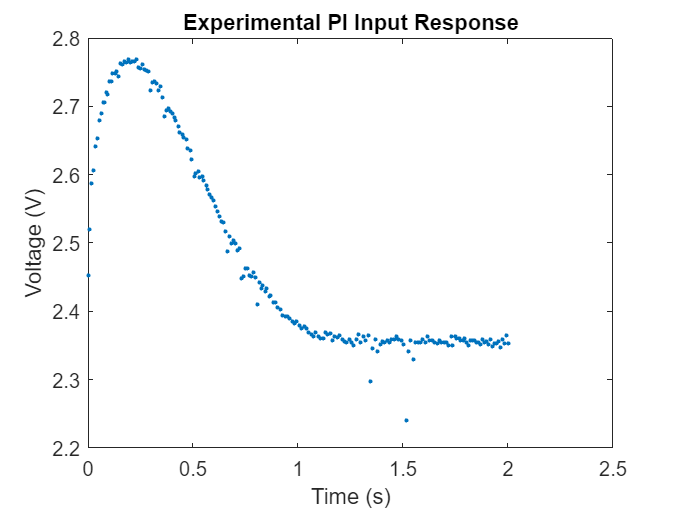


% plot input voltage
plot(time,input, '.')
title("Experimental PI Input Response")
xlabel("Time (s)")
ylabel("Voltage (V)")

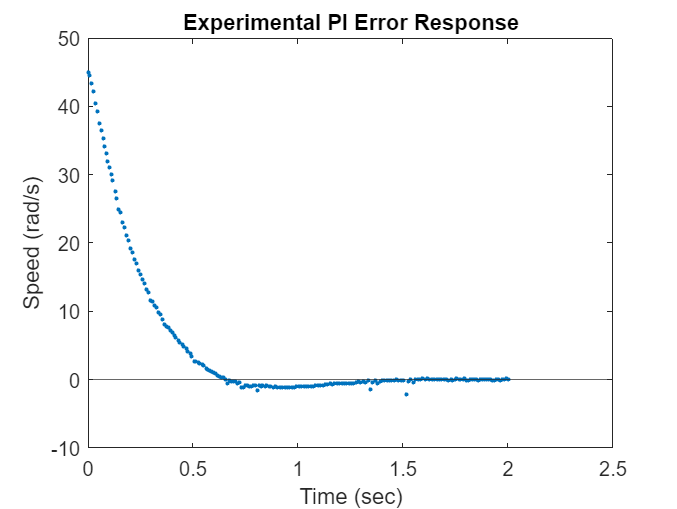


% plot error 
% plot error response
plot(time, error, '.')
yline(0)
title("Experimental PI Error Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")